# YOLOX Inference(五行code)

% Bulit on 2023.12.07 by Fred Liu
% MATLAB 2023b update
% Add-ons: Computer Vision Toolbox Automated Visual Inspection Library

## **YOLOX**

**載入YOLOX模型(Tiny)**

detector = yoloxObjectDetector("tiny-coco")

detector =   yoloxObjectDetector with properties:

                 ClassNames: {80×1 cell}
                  InputSize: [640 640 3]
    NormalizationStatistics: [1×1 struct]
                  ModelName: 'small-coco'


**載入影像**

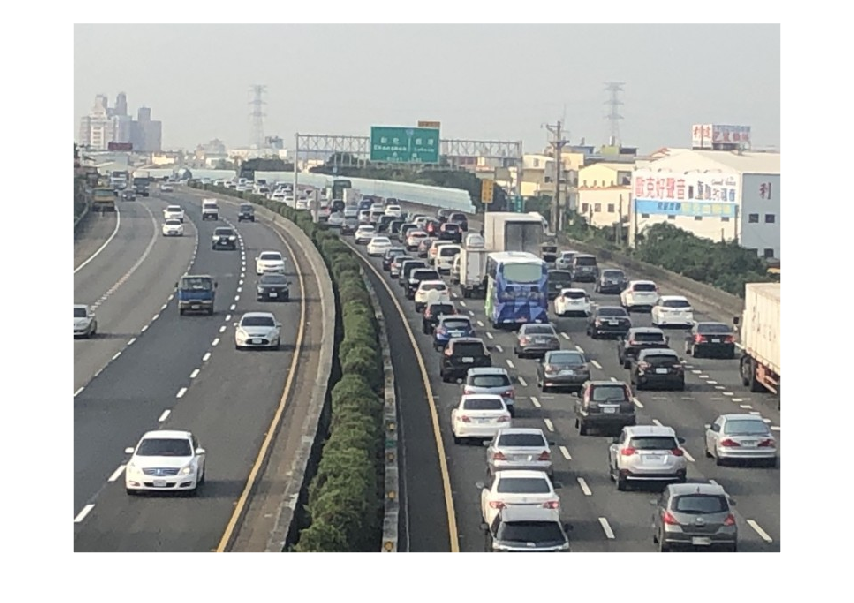

img = imread('highway.jpg'); figure,imshow(img)

**進行辨識**

[bboxes,scores,labels] = detect(detector,img);

**畫標記框與顯示**

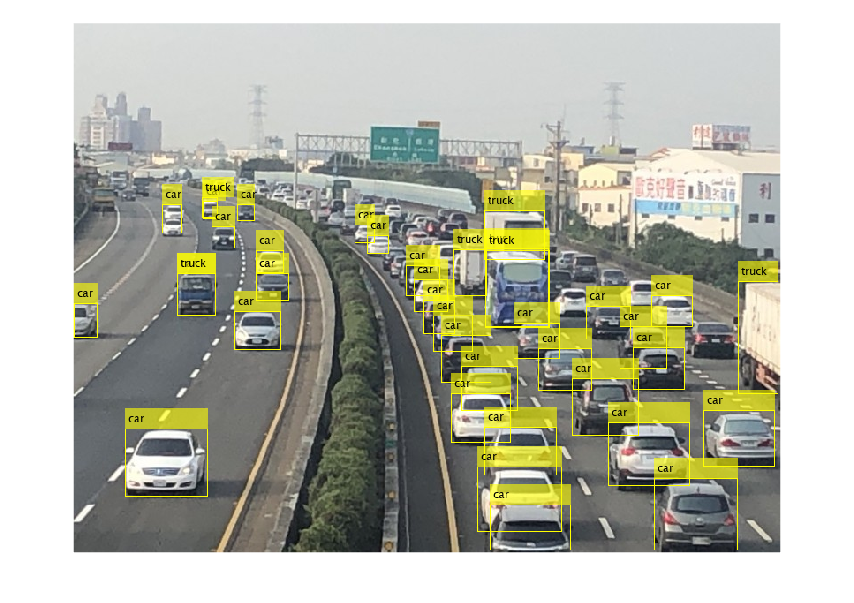

detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure,imshow(detectedImg)

## **Small YOLOX**

detector2 = yoloxObjectDetector("small-coco")

detector2 =   yoloxObjectDetector with properties:

                 ClassNames: {80×1 cell}
                  InputSize: [640 640 3]
    NormalizationStatistics: [1×1 struct]
                  ModelName: 'small-coco'


[bboxes2,scores2,labels2] = detect(detector2,img);
detectedImg2 = insertObjectAnnotation(img,"Rectangle",bboxes2,labels2);
figure,imshow(detectedImg2)

**Small YOLOX Th = 0.2**

tic
[bboxes3,scores3,labels3] = detect(detector2,img,Threshold=0.2); %'Threshold', 0.2
toc

Elapsed time is 0.203828 seconds.


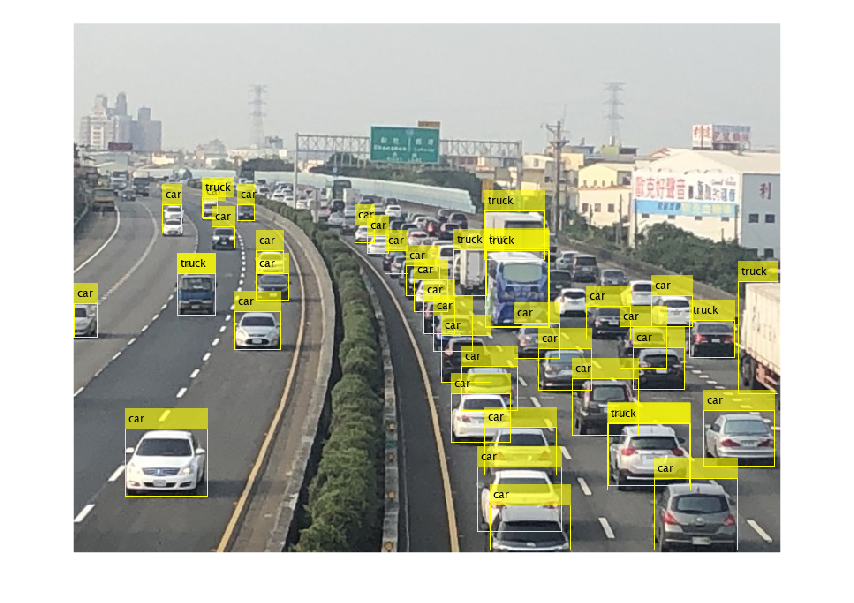

detectedImg3 = insertObjectAnnotation(img,"Rectangle",bboxes3,labels3);
figure,imshow(detectedImg3)

**Speed Up Function**

**It need to download "GPU Coder Interface for Deep Learning" support package**

tic
[bboxes4,scores4,labels4] = detect(detector2,img,'Threshold',0.15,'Acceleration','mex'); %'Threshold', 0.2

Generating MEX for cudnn target. 


toc

Elapsed time is 64.360149 seconds.


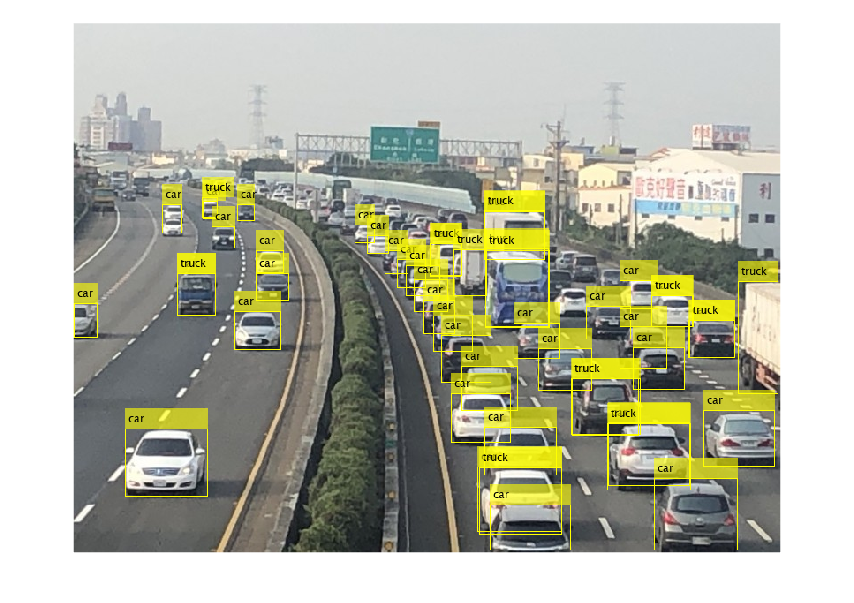

detectedImg4 = insertObjectAnnotation(img,"Rectangle",bboxes4,labels4);
figure,imshow(detectedImg4)